# Structural Testing:

# Test file for return winsorising & covaraince regulirisation

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 31/08/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

**NEEDED DATA: **

**ASSET Px_Last**

"DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat"

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

Set path for data helper functions

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes//datahelpers/functions/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

**Set Directories & Load Data**

Load Processed Signal and Asset Class data

fileName = 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)

x = M_Ret_TT.INDI25_Index;
test_winsor = winsor(x,[10 90]);

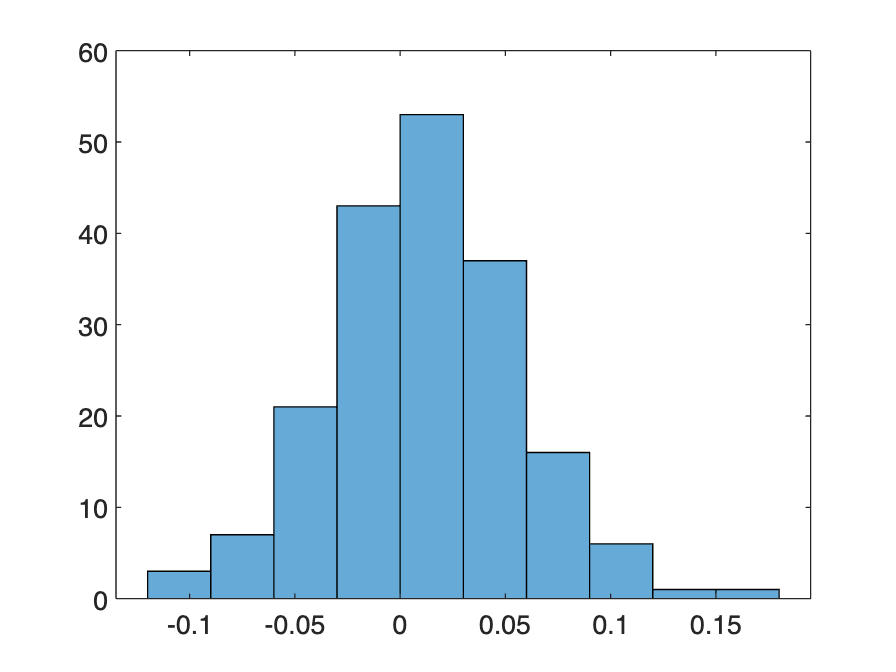

histogram(x);

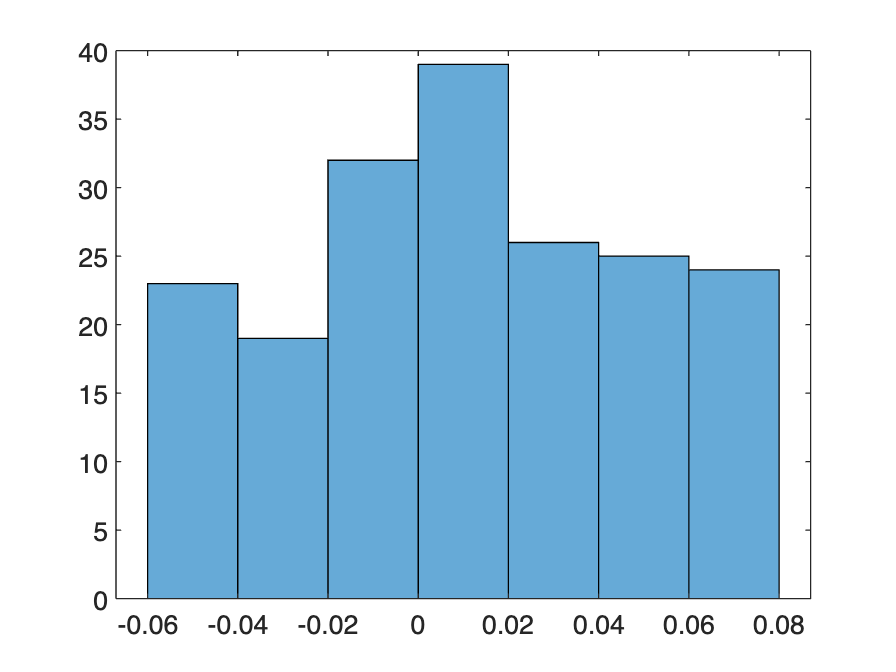

histogram(test_winsor);

Return_matrix = table2array(M_Ret_TT);
% Return_matrix = M_Ret_TT.INDI25_Index;

[wx,b,ui,li] = winsorise(Return_matrix);

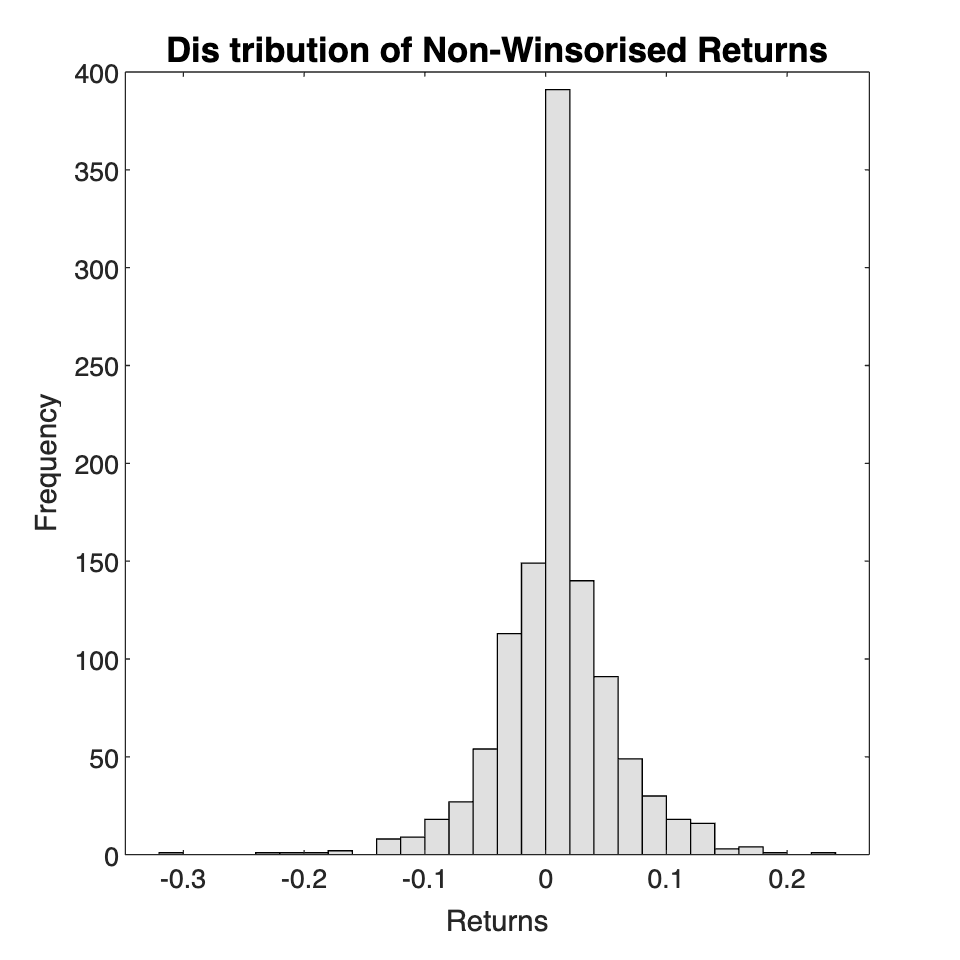

figure('InnerPosition', [100, 100, 600, 600]);
histogram(Return_matrix, 'FaceColor', [0.8, 0.8, 0.8])
title("Dis tribution of Non-Winsorised Returns" ,'FontSize', 13)
% include the legend
xlabel("Returns")
ylabel("Frequency")

Non_Winsorided_Return_Dist = gcf;

#### **Export Non-Winsorised Returns Plot**

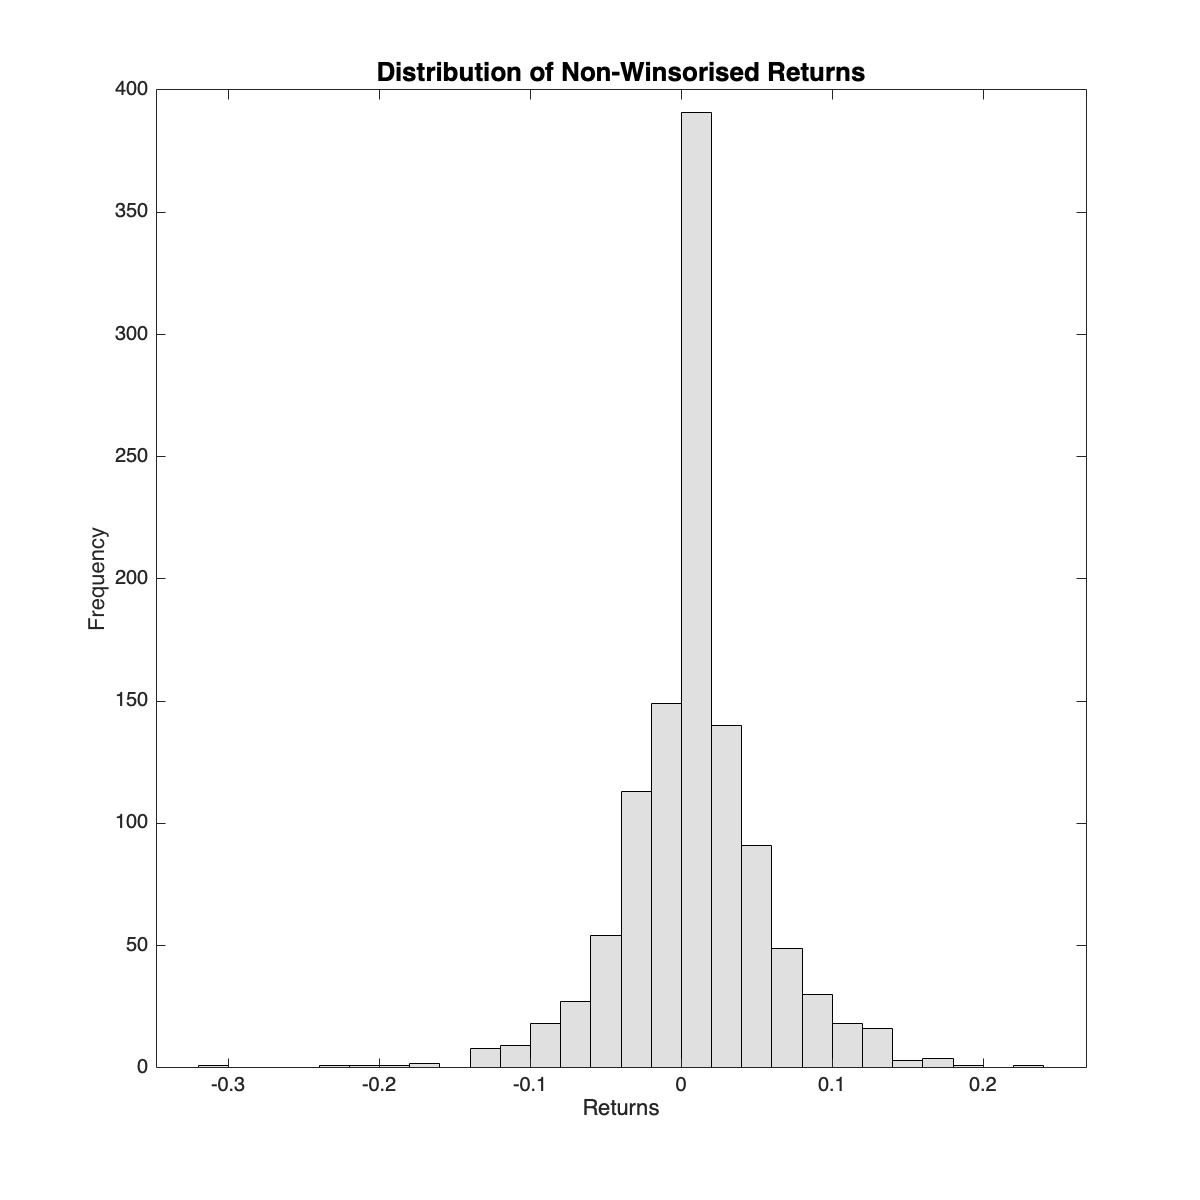

exportName = 'Non_Winsorided_Return_Dist.pdf';
exportgraphics(Non_Winsorided_Return_Dist, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

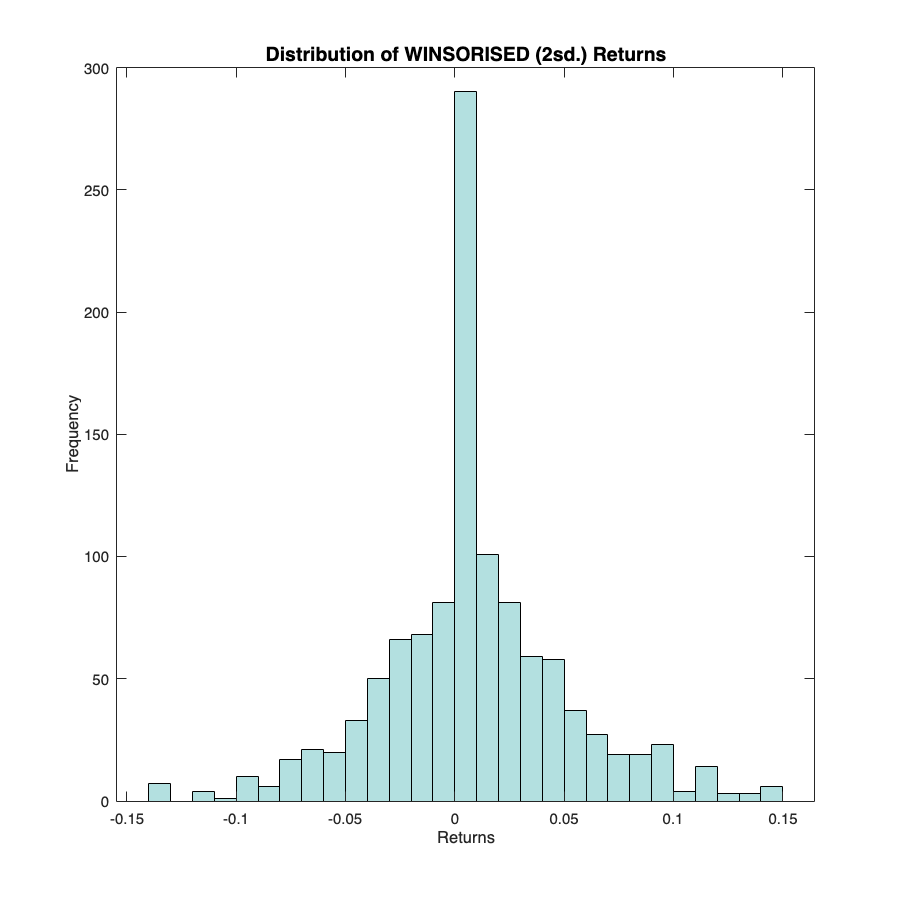

figure('InnerPosition', [100, 100, 600, 600]);
histogram(wx, 'FaceColor', [0.5, 0.8, 0.8])
title("Distribution of WINSORISED (2sd.) Returns" ,'FontSize', 13)
% include the legend
xlabel("Returns")
ylabel("Frequency")

Winsorided2_Return_Dist = gcf;

#### **Export Winsorised2 Returns Plot**

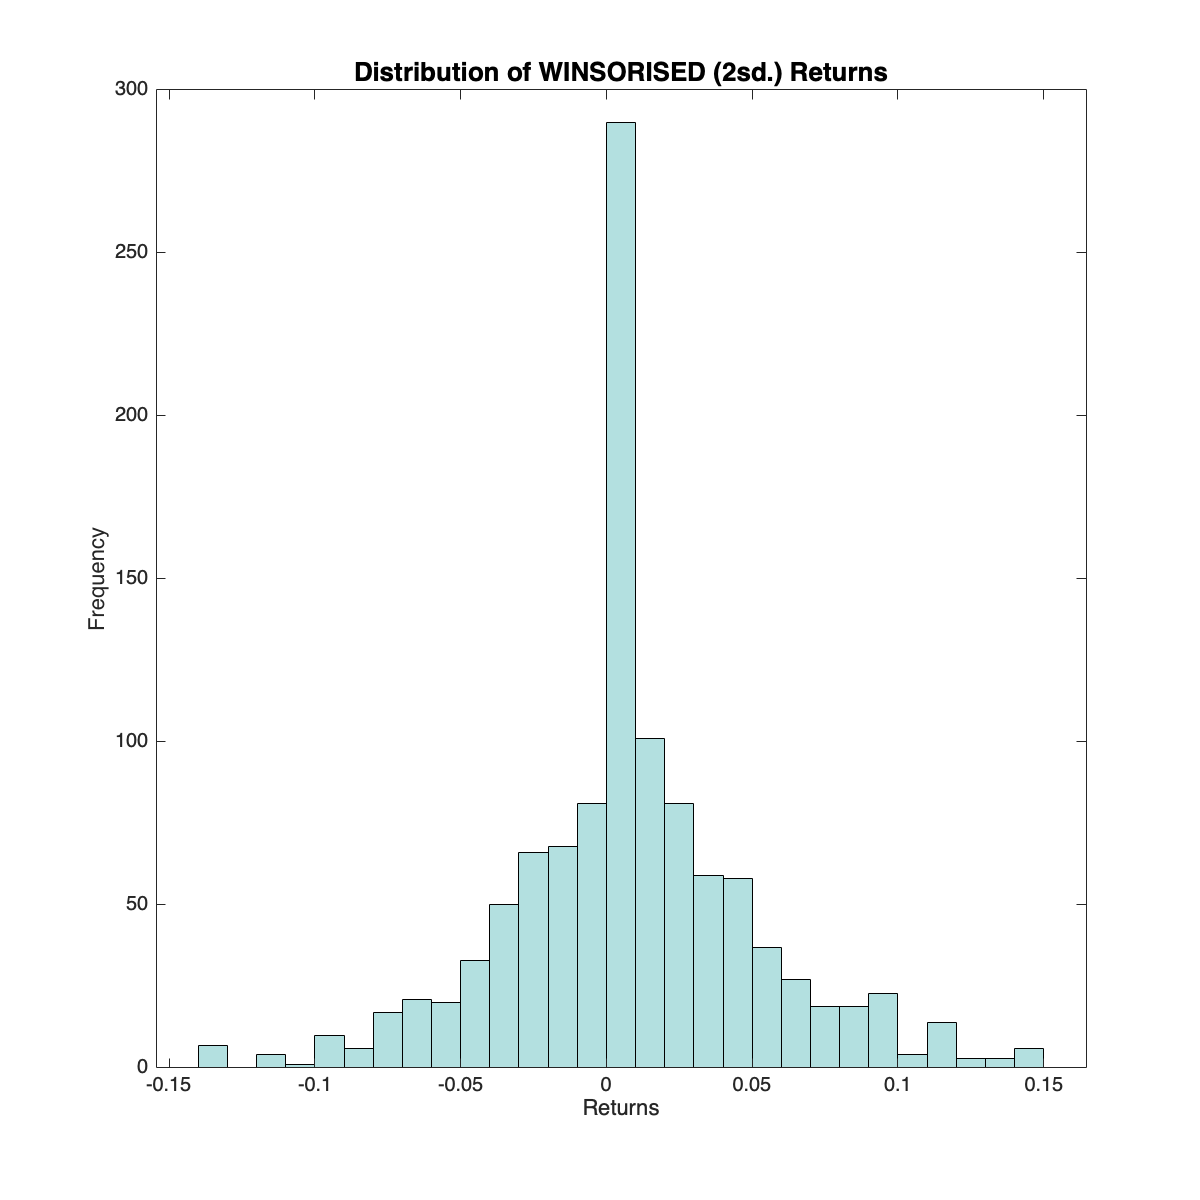

exportName = 'Winsorided2_Return_Dist.pdf';
exportgraphics(Winsorided2_Return_Dist, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

load 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';

# Test Helper functions:

## 1. Geometric average Fn

geo_ave_test = geo_ave(M_Ret_TT,12)

geo_ave_test =     0.0840    0.0846    0.1375    0.0496    0.1001    0.0657


## 2. Geometric Sharpe Ratio Fn

geo_sr_test = geo_sr(M_Ret_TT,12)

geo_sr_test =     3.1738    3.1969    5.0836    1.9024    3.7597    2.5044
